clc
clear all
load('data_gen.mat')
name='boat';
x0 = load_image(name,M);
x0 = rescale( sum(x0,3) );
x=zeros(3*M*N,1);
x(1:M*N)=reshape(x0,M*N,1);
b=A*x;
clf;
% subplot(1,2,2)
% imageplot(reshape(b(1:M*N),M,N));
% subplot(1,2,1)
% imageplot(x0)
tol=10^-10;
norm(x0-reshape(b(1:M*N),M,N),'fro');
save(name,"b","x0","x")

clc
clear all
load('data_gen.mat')
name='boat';
load(name)
rng(0);
tol=10^-6;
MaxIt=70;
NN=3*M*N;
tic
tau1=sum(abs(A));
tau=1./sum(abs(A));
gamma=1./sum(abs(A'));
toc

Elapsed time is 0.286353 seconds.


lambda=0.9999/norma;
noise=0.05;
b_delta=b+noise*(-1+2*rand(NN,1));
error=10^6;
fr=1/norm(K,'fro')^2;
Noisy_Image=reshape(b_delta(1:M*N),M,N);
True_Image=reshape(x(1:M*N),M,N);
Ssim_Noisy=ssim(Noisy_Image,True_Image);
Psnr_Noisy=psnr(Noisy_Image,True_Image);
MSE_Noisy=norm(Noisy_Image-True_Image,'fro')^2/(M*N);
Init_vector=zeros(NN,1);

error=norm(b_delta-x);
uk=Init_vector;
xold=Init_vector;
xk=Init_vector;
pk=Init_vector;
EA=b_delta;
step=0;
res=zeros(NN,1);
res1=zeros(NN,1);
Early_stopping_time=0;
Early_stopping_Iteration=0;
tic
Time=0;
Iter=0;
k=0;
for k=1:MaxIt
        uk=uk+gamma'.*(A*(pk+xk-xold)-b_delta);
        xold=pk;
        x_aux=pk-tau.*A'*uk;
        xk(1:M*N)=max(min(x_aux(1:M*N),1),0);
        for i=1:M*N
                xk(M*N+i,1)=(1-tau(M*N+i)/max(tau(M*N+i),sqrt(x_aux(M*N+i)^2+x_aux(2*M*N+i)^2)))*x_aux(M*N+i);
                xk(2*M*N+i,1)=(1-tau(2*M*N+i)/max(tau(2*M*N+i),sqrt(x_aux(M*N+i)^2+x_aux(2*M*N+i)^2)))*x_aux(2*M*N+i);
        end
        res=A*xk-b_delta;
        alpha1=norm(res)^2;
        res1=A'*res;
        alpha2=res1'*(tau1'.*res1);
        step=(alpha1/alpha2);
        pk=xk-step*tau1'.*res1;
        if error>norm(pk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(pk-x);
            EA=pk;
        end
        if error>norm(xk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(xk-x);
            EA=xk;
        end
        if error>tol
            Time=toc;
            Iter=k;
        end
        pk(1:M*N)=max(min(pk(1:M*N),1),0);

end
 Early_stopping_Iteration_AL=Early_stopping_Iteration;
 Early_stopping_time_AL=Early_stopping_time;
 Image_AL=reshape(EA(1:M*N),M,N);
 Ssim_AL=ssim(Image_AL,True_Image);
 Psnr_AL=psnr(Image_AL,True_Image);
 MSE_AL=norm(Image_AL-True_Image,'fro')^2/(M*N);
 Time_AL=Time;
 Iter_AL=Iter;

error=norm(b_delta-x);
uk=Init_vector;
xold=Init_vector;
xk=Init_vector;
pk=Init_vector;
EA=b_delta;
step=1/normest(A*(tau1.*A'));

res=zeros(NN,1);
res1=zeros(NN,1);
Early_stopping_time=0;
Early_stopping_Iteration=0;
tic
Time=0;
Iter=0;
k=0;
for k=1:MaxIt
        uk=uk+gamma'.*(A*(pk+xk-xold)-b_delta);
        xold=pk;
        x_aux=pk-tau.*A'*uk;
        xk(1:M*N)=max(min(x_aux(1:M*N),1),0);
        for i=1:M*N
                xk(M*N+i,1)=(1-tau(M*N+i)/max(tau(M*N+i),sqrt(x_aux(M*N+i)^2+x_aux(2*M*N+i)^2)))*x_aux(M*N+i);
                xk(2*M*N+i,1)=(1-tau(2*M*N+i)/max(tau(2*M*N+i),sqrt(x_aux(M*N+i)^2+x_aux(2*M*N+i)^2)))*x_aux(2*M*N+i);
        end
        res=A*xk-b_delta;
        res1=A'*res;
        pk=xk-step*tau1'.*res1;
        if error>norm(pk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(pk-x);
            EA=pk;
        end
        if error>norm(xk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(xk-x);
            EA=xk;
        end
        if error>tol
            Time=toc;
            Iter=k;
        end
        pk(1:M*N)=max(min(pk(1:M*N),1),0);

end
 Early_stopping_Iteration_L=Early_stopping_Iteration;
 Early_stopping_time_L=Early_stopping_time;
 Image_L=reshape(EA(1:M*N),M,N);
 Ssim_L=ssim(Image_L,True_Image);
 Psnr_L=psnr(Image_L,True_Image);
 MSE_L=norm(Image_L-True_Image,'fro')^2/(M*N);
 Time_L=Time;
 Iter_L=Iter;

tau=1./(1.4*sum(abs(A)));
gamma=1./(1.4*sum(abs(A')));
error=norm(b_delta-x);
uk=Init_vector;
xold=Init_vector;
xk=Init_vector;
pk=Init_vector;
EA=b_delta;
Early_stopping_time=0;
Early_stopping_Iteration=0;
tic
Time=0;
Iter=0;
k=0;
for k=1:MaxIt
        uk=uk+gamma'.*(A*(pk+xk-xold)-b_delta);
        xold=pk;
        x_aux=pk-tau.*A'*uk;
        xk(1:M*N)=max(min(x_aux(1:M*N),1),0);
        for i=1:M*N
                xk(M*N+i,1)=(1-tau(M*N+i)/max(tau(M*N+i),sqrt(x_aux(M*N+i)^2+x_aux(2*M*N+i)^2)))*x_aux(M*N+i);
                xk(2*M*N+i,1)=(1-tau(2*M*N+i)/max(tau(2*M*N+i),sqrt(x_aux(M*N+i)^2+x_aux(2*M*N+i)^2)))*x_aux(2*M*N+i);
        end
        pk=xk;
        if error>norm(pk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(pk-x);
            EA=pk;
        end
        if error>tol
            Time=toc;
            Iter=k;
        end
end
 Early_stopping_Iteration_PP=Early_stopping_Iteration;
 Early_stopping_time_PP=Early_stopping_time;
 Image_PP=reshape(EA(1:M*N),M,N);
 Ssim_PP=ssim(Image_PP,True_Image);
 Psnr_PP=psnr(Image_PP,True_Image);
 MSE_PP=norm(Image_PP-True_Image,'fro')^2/(M*N);
 Time_PP=Time;
 Iter_PP=Iter;

error=norm(b_delta-x);
uk=Init_vector;
xold=Init_vector;
xk=Init_vector;
pk=Init_vector;
EA=b_delta;
step=fr;
res=zeros(NN,1);
res1=zeros(NN,1);
Early_stopping_time=0;
Early_stopping_Iteration=0;
tic
Time=0;
Iter=0;
for k=1:MaxIt
        uk=uk+lambda*(A*(pk+xk-xold)-b_delta);
        xold=pk;
        x_aux=pk-lambda*A'*uk;
        xk(1:M*N)=max(min(x_aux(1:M*N),1),0);
        for i=1:M*N
                xk(M*N+i,1)=(1-lambda/max(lambda,sqrt(x_aux(M*N+i)^2+x_aux(2*M*N+i)^2)))*x_aux(M*N+i);
                xk(2*M*N+i,1)=(1-lambda/max(lambda,sqrt(x_aux(M*N+i)^2+x_aux(2*M*N+i)^2)))*x_aux(2*M*N+i);
        end
        pk=xk;
        norm(pk-x)
        if error>norm(pk-x)
            Early_stopping_Iteration=k
            Early_stopping_time=toc;
            error=norm(pk-x)
            EA=pk;
        end
end

ans = 144.0944

ans = 114.8149

ans = 77.2127

ans = 36.3800

Early_stopping_Iteration = 4

error = 36.3800

ans = 11.6852

Early_stopping_Iteration = 5

error = 11.6852

ans = 41.8285

ans = 59.9798

ans = 65.8815

ans = 67.3178

ans = 65.3755

ans = 59.8717

ans = 51.2477

ans = 40.5540

ans = 29.6802

ans = 22.0995

ans = 21.8992

ans = 27.1257

ans = 32.6962

ans = 36.0794

ans = 36.4787

ans = 33.9317

ans = 29.0003

ans = 22.6709

ans = 16.4802

ans = 12.9180

ans = 13.9122

ans = 17.3108

ans = 20.3860

ans = 21.9812

ans = 21.7938

ans = 19.9575

ans = 16.9028

ans = 13.3288

ans = 10.2878

Early_stopping_Iteration = 34

error = 10.2878

ans = 9.1100

Early_stopping_Iteration = 35

error = 9.1100

ans = 10.0927

ans = 11.9070

ans = 13.3766

ans = 13.9952

ans = 13.6613

ans = 12.5161

ans = 10.8786

ans = 9.2185

ans = 8.0919

Early_stopping_Iteration = 44

error = 8.0919

ans = 7.8660

Early_stopping_Iteration = 45

error = 7.8660

ans = 8.3621

ans = 9.0535

ans = 9.5141

ans = 9.5451

ans = 9.1328

ans = 8.4016

ans = 7.5777

Early_stopping_Iteration = 52

error = 7.5777

ans = 6.9407

Early_stopping_Iteration = 53

error = 6.9407

ans = 6.7131

Early_stopping_Iteration = 54

error = 6.7131

ans = 6.9152

ans = 7.3627

ans = 7.8265

ans = 8.1523

ans = 8.2860

ans = 8.2566

ans = 8.1478

ans = 8.0631

ans = 8.0853

ans = 8.2428

ans = 8.5047

ans = 8.8063

ans = 9.0828

ans = 9.2923

ans = 9.4229

ans = 9.4887

 Early_stopping_Iteration_PD=Early_stopping_Iteration;
 Early_stopping_time_PD=Early_stopping_time;
 Image_PD=reshape(EA(1:M*N),M,N);
 Ssim_PD=ssim(Image_PD,True_Image);
 Psnr_PD=psnr(Image_PD,True_Image);
 MSE_PD=norm(Image_PD-True_Image,'fro')^2/(M*N);
 Time_PD=Time;
 Iter_PD=Iter;

LastName = {'Noisy_Image';'Primal Dual W'; 'Primal Dual'; 'PD Landweber';'PD Landweber adaptive'};
Iteration_Early_stopping = [0;Early_stopping_Iteration_PP;Early_stopping_Iteration_PD;Early_stopping_Iteration_L;Early_stopping_Iteration_AL];
Time_Early_stopping = [0;Early_stopping_time_PP;Early_stopping_time_PD;Early_stopping_time_L;Early_stopping_time_AL];
SSIM_Images=[Ssim_Noisy;Ssim_PP;Ssim_PD;Ssim_L;Ssim_AL];
PSNR_Images =[Psnr_Noisy;Psnr_PP;Psnr_PD;Psnr_L;Psnr_AL];
MSE_Images =[MSE_Noisy;MSE_PP;MSE_PD;MSE_L;MSE_AL];
LastName1 = {'Primal Dual W'; 'Primal Dual'; 'PD Landweber';'PD Landweber adaptive'};
Iter_Tol_Images =[Iter_PP;Iter_PD;Iter_L;Iter_AL];
Time_Tol_Images =[Time_PP;Time_PD;Time_L;Time_AL];

T1 = table(Iteration_Early_stopping,Time_Early_stopping,SSIM_Images,PSNR_Images, MSE_Images,'RowNames',LastName)

T1 = 5×5 table
                             Iteration_Early_stopping    Time_Early_stopping    SSIM_Images    PSNR_Images    MSE_Images
                             ________________________    ___________________    ___________    ___________    __________

    Noisy_Image                          0                           0            0.44681         21.48         0.007112
    Primal Dual W                        5                      1.7226            0.85814        27.375        0.0018301
    Primal Dual                         54                      8.0271            0.89275        32.361       0.00058057
    PD Landweber                         3                     0.89861            0.81154        28.242        0.0017131
    PD Landw

T2 = table(Iter_Tol_Images,Time_Tol_Images,'RowNames',LastName1)

T2 = 4×2 table
                             Iter_Tol_Images    Time_Tol_Images
                             _______________    _______________

    Primal Dual W                  70               19.136     
    Primal Dual                     0                    0     
    PD Landweber                   70               20.871     
    PD Landweber adaptive          70               20.014     


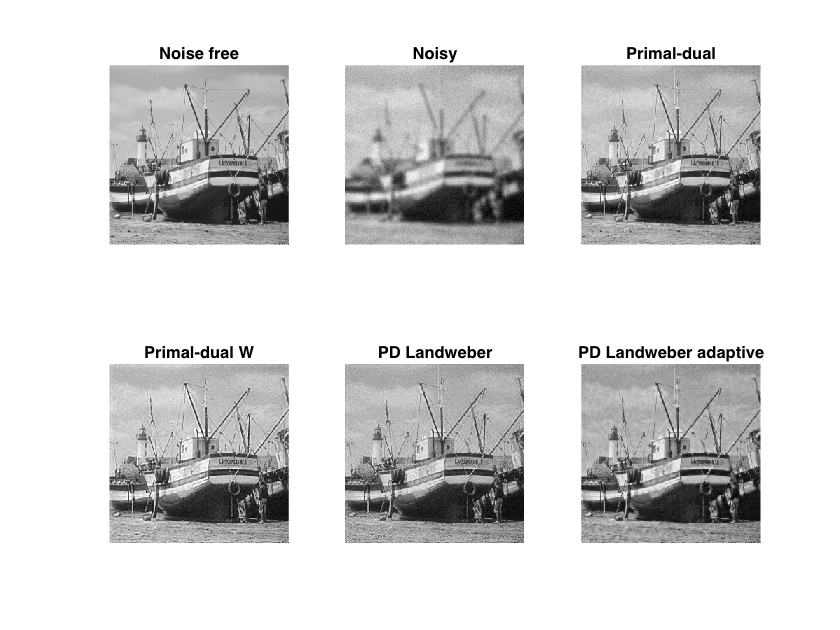

clf;
subplot(2,3,2)
imageplot(reshape(b_delta(1:M*N),M,N),'Noisy');
subplot(2,3,1)
imageplot(x0,'Noise free');
subplot(2,3,4)
imageplot(reshape(Image_PP(1:M*N),M,N),'Primal-dual W');
subplot(2,3,3)
imageplot(reshape(Image_PD(1:M*N),M,N),'Primal-dual');
subplot(2,3,6)
imageplot(reshape(Image_AL(1:M*N),M,N),'PD Landweber adaptive');
subplot(2,3,5)
imageplot(reshape(Image_L(1:M*N),M,N),'PD Landweber');